Checking for Data Validity - Reading Flight Price Data

clc
clear
close all

% Read Data - Busiest Routes
load FlightData_2025_BusiestRoutes.mat


% Best Flight Data

% Find Size
[rB cB] = size(bestFlights);

% Reshape Matrix
bestFlightsReshaped = reshape(bestFlights, rB*cB, 1);
bestPricesReshaped = reshape(bestPrices, rB*cB, 1);

% Remove Empty Cells
bestFlightsReshaped = bestFlightsReshaped(bestFlightsReshaped ~= "");
bestPricesReshaped = bestPricesReshaped(bestFlightsReshaped ~= "");

% Remove Spaces in Airline Names
bestFlightsReshaped = strrep(bestFlightsReshaped, ' ', '');

% Find Unique Airlines and Occurrence Frequency within Best Flights
[uniqueBestFlights, ~, idx] = unique(bestFlightsReshaped);
bestFlightCounts = histcounts(idx, 1:length(uniqueBestFlights) + 1);

% Unique Best Flights and Flight Counts
fprintf("\n\nUnique Best Flights and Flight Counts:\n")



Unique Best Flights and Flight Counts:


uniqueBestFlights

uniqueBestFlights = 3×1 string array
    "AirIndia"
    "AkasaAir"
    "IndiGo"


bestFlightCounts = bestFlightCounts'

bestFlightCounts =     27
    56
    34


bestFlightMktShare = bestFlightCounts*100/sum(bestFlightCounts)

bestFlightMktShare =    23.0769
   47.8632
   29.0598


% Other/All Flight Data
% Find Size
[rO cO] = size(otherFlights);

% Reshape Matrix
otherFlightsReshaped = reshape(otherFlights, rO*cO, 1);
otherPricesReshaped = reshape(otherPrices, rO*cO, 1);

% Remove Empty Cells
otherFlightsReshaped = otherFlightsReshaped(otherFlightsReshaped ~= "");
otherPricesReshaped = otherPricesReshaped(otherFlightsReshaped ~= "");

% Remove Spaces in Airline Names
otherFlightsReshaped = strrep(otherFlightsReshaped, ' ', '');

% Find Unique Airlines and Occurrence Frequency within Best Flights
[uniqueOtherFlights, ~, idx] = unique(otherFlightsReshaped);
otherFlightCounts = histcounts(idx, 1:length(uniqueOtherFlights) + 1);

% Unique Other Flights and Flight Counts
fprintf("\n\nUnique Other Flights and Flight Counts:\n")



Unique Other Flights and Flight Counts:


uniqueOtherFlights

uniqueOtherFlights = 4×1 string array
    "AirIndia"
    "AkasaAir"
    "IndiGo"
    "SpiceJet"


otherFlightCounts = otherFlightCounts'

otherFlightCounts =    490
    36
   464
    51


otherFlightMktShare = otherFlightCounts*100/sum(otherFlightCounts)

otherFlightMktShare =    47.0701
    3.4582
   44.5725
    4.8991


allFlights = [bestFlightsReshaped ; otherFlightsReshaped];
allPrices = [bestPricesReshaped ; otherPricesReshaped];

% Find Unique Airlines and Occurrence Frequency within Best Flights
[uniqueAllFlights, ~, idx] = unique(allFlights);
allFlightCounts = histcounts(idx, 1:length(uniqueAllFlights) + 1);

% Unique Total Flights and Flight Counts
fprintf("\n\nUnique Total Flights and Flight Counts:\n")



Unique Total Flights and Flight Counts:


uniqueAllFlights

uniqueAllFlights = 4×1 string array
    "AirIndia"
    "AkasaAir"
    "IndiGo"
    "SpiceJet"


allFlightCounts = allFlightCounts'

allFlightCounts =    517
    92
   498
    51


busiestRouteMktShare = allFlightCounts*100/sum(allFlightCounts)

busiestRouteMktShare =    44.6459
    7.9447
   43.0052
    4.4041



allFlightsCtg = categorical(allFlights);

allFlightsCtg = 1158×1 categorical array
     AkasaAir 
     AkasaAir 
     AkasaAir 
     AkasaAir 
     IndiGo 
     AkasaAir 
     AkasaAir 
     AkasaAir 
     AkasaAir 
     AkasaAir 
     AkasaAir 
     AkasaAir 
     AkasaAir 
     AkasaAir 
     AkasaAir 
     AkasaAir 
     AkasaAir 
     AkasaAir 
     IndiGo 
     AkasaAir 
     AirIndia 
     IndiGo 
     AkasaAir 
     AirIndia 
     IndiGo 
     AkasaAir 
     AirIndia 
     IndiGo 
     AkasaAir 
     AirIndia 



figure
histogram(allFlightsCtg,'Normalization','pdf')
title('Market Share - Busiest Routes')
xlabel('Airline')
ylabel('Market Share')

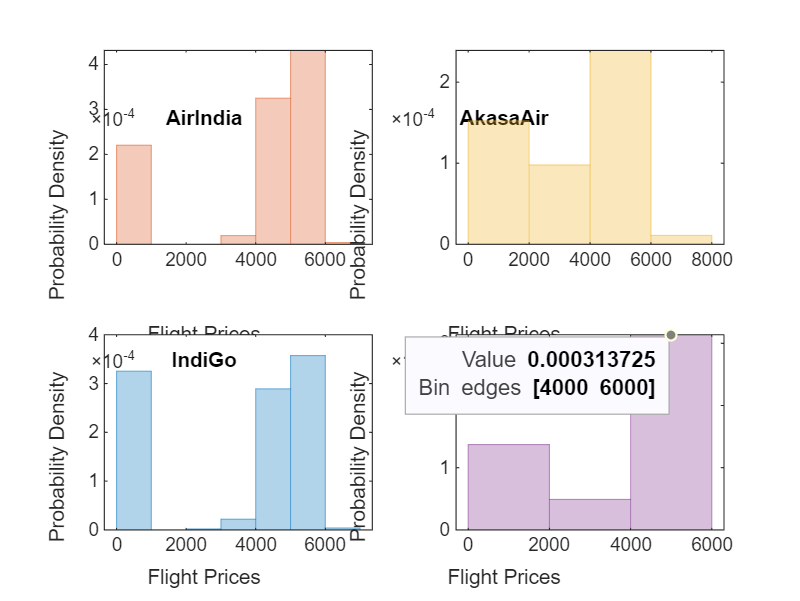

% Colors for the histograms
% Pick Distinct Colors
pColour = [217 13 43;...
            255 99 0;...
            58 70 157;...
            252 216 0];
pColour = pColour/255;

bEdges = [0:1000:10000];

% Create a new figure
figure;
hold on;

% Loop through each Airline and plot its Price histogram
for i = 1:numel(uniqueAllFlights)

    % Get indices for the current string
    idx = allFlights == uniqueAllFlights(i);
    
    % Plot histogram for the current string
    subplot(2,2,i)
    histogram(allPrices(idx), bEdges, ...
        'Normalization','countdensity',...
        'DisplayStyle', 'bar', ...
        'FaceColor', pColour(i, :), 'EdgeColor', pColour(i, :));
    title(uniqueAllFlights(i))
    xlabel('Flight Prices');
    ylabel('Count Density');

end

hold off;


% Define the folder containing the JSON files
fPath = 'C:\Users\ppai\Downloads\AlgoCollusion\';  % Update this path to your folder location

fName = 'Flight Data - 2025 (Tourist Spots)'
% fName = 'Flight Data - 2025 (Busiest Routes)'

dName = "FlightData_2025_TouristSpots"
% dName = 'FlightData_2025_BusiestRoutes'

folderPath = [fPath fName]

% Get a list of all .json files in the folder
jsonFiles = dir(fullfile(folderPath, '*.json'));
nFiles = length(jsonFiles);

% Initialize Variables
deptIDs = strings(nFiles,1);
arrvIDs = strings(nFiles,1);
lowestPrice = zeros(nFiles,1);
priceRange = zeros(nFiles,2);

bestFlights = strings(5,nFiles);
bestPrices = zeros(5,nFiles);

otherFlights = strings(51,nFiles);
otherPrices = zeros(51,nFiles);

% Loop through each file and parse it
for i = 1:length(jsonFiles)
    % Get the full file path
    filePath = fullfile(folderPath, jsonFiles(i).name);

    % Read and parse the JSON data
    try
        % Load JSON data as a MATLAB structure
        jsonData = jsondecode(fileread(filePath));

        % Display or process the JSON data as needed
        fprintf('Parsed data from: %s\n', jsonFiles(i).name);

        % Read Departure and Arrival IDs
        deptIDs(i) = jsonData.search_parameters.departure_id;
        arrvIDs(i) = jsonData.search_parameters.arrival_id;
        
        % Read Departure and Return Dates
        depDate(i) = datetime(jsonData.search_parameters.outbound_date);
        retDate(i) = datetime(jsonData.search_parameters.return_date);

        % Check if the JSON data contains the relevant flight information
        if isfield(jsonData, 'best_flights') || isfield(jsonData, 'other_flights') || isfield(jsonData, 'price_insights')

            % Collect Data from Price Insights
            lowestPrice(i) = jsonData.price_insights.lowest_price;
            priceRange(i,:) = jsonData.price_insights.typical_price_range';
            
            % Collect Data from Best Flights
            if isfield(jsonData,'best_flights')
                if iscell(jsonData.best_flights)
                    s2c = 0;
                elseif isstruct(jsonData.best_flights)
                    s2c = 1;
                end
                for j = 1:length(jsonData.best_flights)
                    if s2c == 0
                        if isfield(jsonData.best_flights{j}, 'price')
                            % Best Flights Insights
                            bestFlights(j,i) = jsonData.best_flights{j}.flights;
                            bestPrices(j,i) = jsonData.best_flights{j}.price;
                        end
                    else
                        if isa(jsonData.best_flights(1).price,'double')
                            % Best Flights Insights
                            bestFlights(j,i) = jsonData.best_flights(j).flights;
                            bestPrices(j,i) = jsonData.best_flights(1).price;
                        end
                    end
                end
            end

            % Collect Data from Other Flights
            if isfield(jsonData,'other_flights')
                if iscell(jsonData.other_flights)
                    s2c = 0;
                elseif isstruct(jsonData.other_flights)
                    s2c = 1;
                end
                for j = 1:length(jsonData.other_flights)
                    if s2c == 0
                        if isfield(jsonData.other_flights{j}, 'price')
                            % Other Flights Insights
                            otherFlights(j,i) = jsonData.other_flights{j}.flights;
                            otherPrices(j,i) = jsonData.other_flights{j}.price;
                        end
                    else
                        if isa(jsonData.other_flights(1).price,'double')
                            % Other Flights Insights
                            otherFlights(j,i) = jsonData.other_flights(j).flights;
                            otherPrices(j,i) = jsonData.other_flights(1).price;
                        end
                    end
                end
            end
        end

    catch ME
        % Handle any errors that occur during parsing
        fprintf('Error parsing %s: %s\n', jsonFiles(i).name, ME.message);
    end

end

save FlightData_2025_TouristSpots...
    deptIDs arrvIDs depDate retDate ...
    lowestPrice priceRange ...
    bestFlights bestPrices ...
    otherFlights otherPrices ...
    nFiles folderPath
    

Addendum

        % if isfield(jsonData,'other_flights')
        %     for j = 1:length(jsonData.other_flights)
        %         if isfield(jsonData.other_flights{j}, 'price')
        %             % Other Flights Insights
        %             otherFlights(j,i) = jsonData.other_flights{j}.flights;
        %             otherPrices(j,i) = jsonData.other_flights{j}.price;
        %         end
        %     end
        % end
        % 
        % % Check if the JSON data contains the relevant flight information
        % if isfield(jsonData, 'best_flights') || isfield(jsonData, 'other_flights')
        %     % Collect flight data from best_flights
        %     if isfield(jsonData, 'best_flights')
        %         bestFlights = jsonData.best_flights;
        %         fprintf('Best flights from: %s\n', jsonFiles(i).name);
        %         % Display a table header
        %         fprintf('%-20s %-10s\n', 'Flight Name', 'Price (INR)');
        %         fprintf('-------------------- ----------\n');
        %         for j = 1:length(bestFlights)
        %             if isfield(bestFlights{j}, 'price')
        %                 fprintf('%-20s %-10d\n', strjoin(bestFlights{j}.flights, ', '), bestFlights{j}.price);
        %             end
        %         end
        %     end
        % 
        %     % Collect flight data from other_flights
        %     if isfield(jsonData, 'other_flights')
        %         otherFlights = jsonData.other_flights;
        %         fprintf('\nOther flights from: %s\n', jsonFiles(i).name);
        %         % Display a table header
        %         fprintf('%-20s %-10s\n', 'Flight Name', 'Price (INR)');
        %         fprintf('-------------------- ----------\n');
        %         for j = 1:length(otherFlights)
        %             if isfield(otherFlights(j), 'price')
        %                 fprintf('%-20s %-10d\n', strjoin(otherFlights(j).flights, ', '), otherFlights(j).price);
        %             end
        %         end
        %     end
        % 
        %     % Display the price insights if available
        %     if isfield(jsonData, 'price_insights')
        %         priceInsights = jsonData.price_insights;
        %         if isfield(priceInsights, 'lowest_price')
        %             fprintf('\nLowest Price: %d\n', priceInsights.lowest_price);
        %         end
        %         if isfield(priceInsights, 'typical_price_range')
        %             fprintf('Typical Price Range: [%d, %d]\n', ...
        %                 priceInsights.typical_price_range(1), ...
        %                 priceInsights.typical_price_range(2));
        %         end
        %     end
        % end
